# 用双输入感知器分类

双输入硬限制神经元被训练为将四个输入向量划分为两个类别。

X 中的四个列向量中的每一个都定义了一个二元素输入向量，行向量 T 定义了向量的目标类别。我们可以使用 PLOTPV 绘制这些向量。

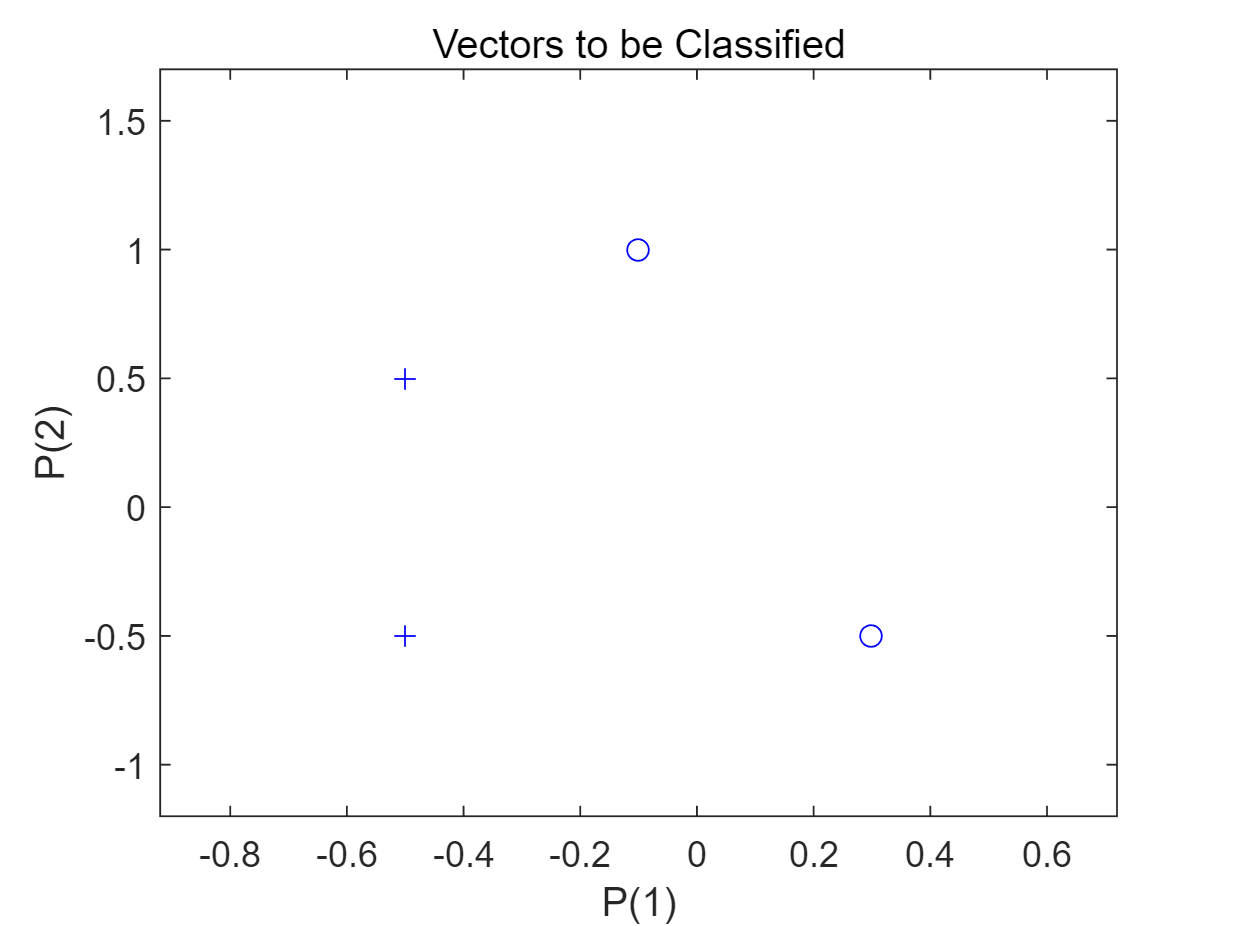

clear
X = [ -0.5 -0.5 +0.3 -0.1;  ...
      -0.5 +0.5 -0.5 +1.0];
T = [1 1 0 0];
plotpv(X,T);

感知器必须将 X 中的四个输入向量正确分类为由 T 定义的两个类别。感知器具有 HARDLIM 神经元。这些神经元能够用一条直线将输入空间分为两个类别（0 和 1）。

这里 PERCEPTRON 创建了一个具有单个神经元的新神经网络。然后针对数据配置网络，这样我们可以检查其初始权重和偏置值。（通常可以跳过配置步骤，因为 ADAPT 或 TRAIN 会自动完成配置。）

net = perceptron;
net = configure(net,X,T);

神经元初次尝试分类时，输入向量会被重新绘制。

初始权重设置为零，因此任何输入都会生成相同的输出，而且分类线甚至不会出现在图上。别担心...我们将对它进行训练！

% plotpv(X,T);
% plotpc(net.IW{1},net.b{1});

此处，输入数据和目标数据转换为顺序数据（元胞数组，其中每个列指示一个时间步）并复制三次以形成序列 XX 和 TT。

ADAPT 针对序列中的每个时间步更新网络，并返回一个作为更好的分类器执行的新网络对象。

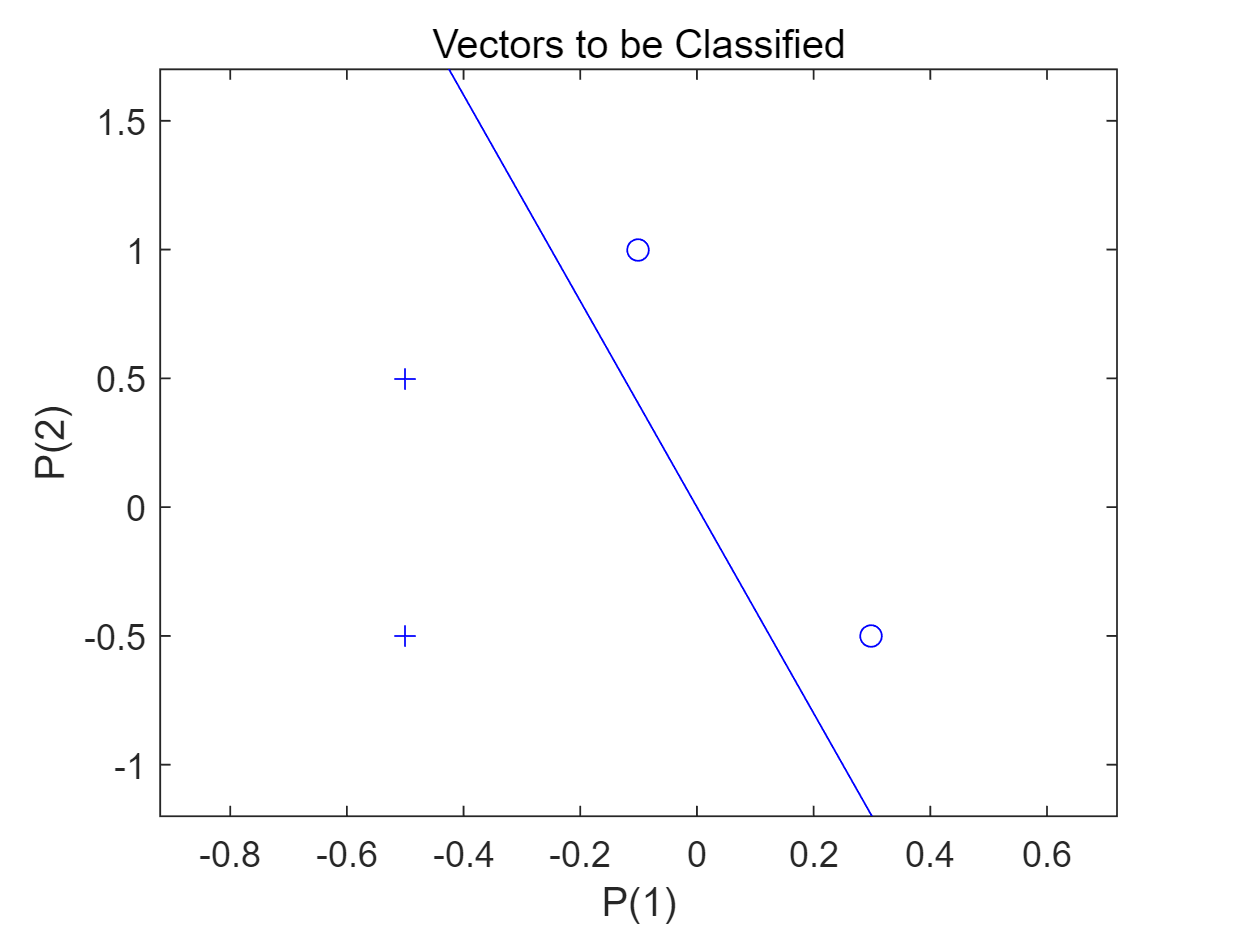

XX = repmat(con2seq(X),1,3);
TT = repmat(con2seq(T),1,3);
net = adapt(net,XX,TT);
plotpc(net.IW{1},net.b{1});

保存训练好的网络 

save net1 net